clear all
close all

fileName = "manyframe_mystery";

rawCSV = csvread(fileName + ".csv",2,0);
t = rawCSV(:,1);
t = t - min(t);

v = rawCSV(:,2);

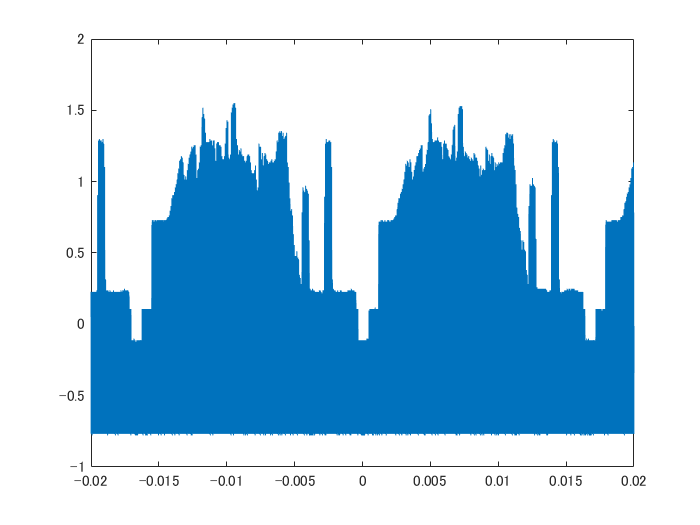

T = mean(diff(t))

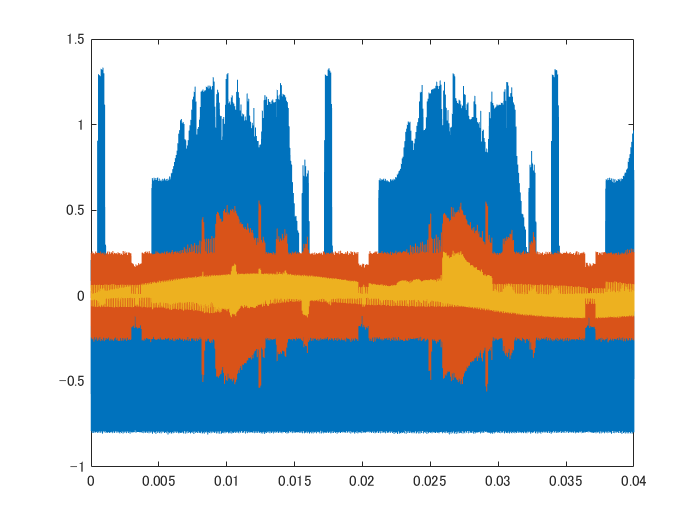


plot(t,v)
% --- glorious fft time/freq vector boilerplate ---
NT = max(t)-min(t)+T;

F = 1/NT;
NF = 1/T;

t = 0:T:NT-T;
f = 0:F:NF-F;

tt = fftshift(t);
tt(tt > tt(end)) = tt(tt > tt(end)) - NT;
ff = fftshift(f);
ff(ff > ff(end)) = ff(ff > ff(end)) - NF;
% --- glorious fft time/freq vector boilerplate ---

VV = fftshift(fft(v));

BWBW = VV;
BWBW(abs(ff) > 2.5e6) = 0;

CC = VV;
CC(abs(ff) < 2.5e6) = 0;

bw = ifft(ifftshift(BWBW));
c = ifft(ifftshift(CC));
phase = c.*sin(2*pi*3579545.454545*t); % ????

PHASEPHASE = fftshift(fft(phase));
PHASEPHASE(abs(ff) > 3e6) = 0;
phase = ifft(ifftshift(PHASEPHASE));

plot(t,[bw; c; phase])